# Xin

starting = tic;

input_path = 'Data/STARmap_data/1000genes/BY3/raw/output/xin/';
dims = [400 400 36 4 6];

useGPU = false;

%curr_gpu = gpuDevice();
new_run = new_STARMapDataset(input_path, dims, 'useGPU', useGPU);

Pipeline Obj is generated...


new_run = new_run.LoadCellImages;

====Load Cell Segmentation Images====


%new_run = new_run.LoadRawImages;

new_run = new_run.LoadCodebook;

====Load Codebook====
doReverse: 1


new_run = new_run.LoadRegisteredImages(input_path);

====Loading registered images====
Loading round 3...[time = 0.55 s]
Loading round 1...[time = 0.81 s]
Loading round 2...[time = 0.62 s]
Loading round 4...[time = 0.55 s]
Loading round 5...[time = 0.57 s]
Loading round 6...[time = 0.60 s]
Collapsed to size 400 by 400 by 36
Collapsing round 1
Collapsing round 2
Collapsing round 3
Collapsing round 4
Collapsing round 5
Collapsing round 6


====Spot Finding====
Method: barcode
Get barcodes for Round 1....Q: 1.00, C: 568321[time = 0.93 s]
Get barcodes for Round 2....Q: 0.99, C: 737585[time = 0.88 s]
Get barcodes for Round 3....Q: 0.99, C: 726906[time = 0.86 s]
Get barcodes for Round 4....Q: 0.99, C: 715660[time = 0.89 s]
Get barcodes for Round 5....Q: 0.99, C: 667621[time = 0.85 s]
Get barcodes for Round 6....Q: 0.99, C: 633850[time = 0.83 s]
The global quality score threshold for barcode calling is: 4.20 


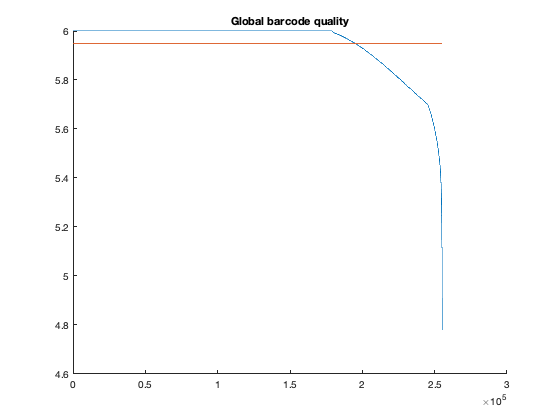

Iterate through clusters...[time = 50.83 s]
Number of spots found by barcode: 3019
[time = 50.86 s]


%new_run = new_run.SwapChannels;
%new_run = new_run.MinMaxNormalize;
%new_run = new_run.MorphoRecon;
%new_run = new_run.GlobalRegistration;
%new_run = new_run.LocalRegistration('Iterations', [100 100 100 100 10]);
%new_run = new_run.LocalRegistration('Iterations', 60);
new_run = new_run.SpotFinding('Method', "barcode", 'qualityThreshold', 0.7, 'volumeThreshold', 10, 'showPlots',true);

new_run = new_run.ReadsExtraction('showPlots',false); 

====Reads Extraction====
Geting color sequence for each voxel...

Geting max color...
0 
Decoding...



new_run = new_run.ReadsFiltration('showPlots',false);

====Reads Filtration====
Base in both ends: C --- C
Filtration Statistics:
0.470023 [1419 / 3019] percent of good reads are CNNNNNC
0.469361 [1417 / 3019] percent of good reads are in codebook
0.998591 [1417 / 1419] percent of CNNNNNC reads are in codebook


%new_run = new_run.SaveReads;
%new_run = new_run.AssignReads;
new_run.jobFinished

ans = struct with fields:
               ImageSize: [400 400 36 4 6]
           LoadRawImages: 0
          LoadCellImages: 1
            LoadCodebook: 1
    LoadRegisteredImages: 1
             SpotFinding: ["1"    "barcode"    "0.7"    "10"    "true"]
         ReadsExtraction: [1 3 3 1]
         ReadsFiltration: 1



%reset(curr_gpu)
toc(starting)

Elapsed time is 264.044648 seconds.
